% cleaning
clc
clear

% importing data
df1=readtable("..\data\experimental-data-1.csv")

df1 = 10×4 table
    dimension    value    uncertainty      uom  
    _________    _____    ___________    _______

     {'d1' }      55           1         {'CMT'}
     {'d2' }      60           1         {'CMT'}
     {'d3' }      65           1         {'CMT'}
     {'d4' }      70           1         {'CMT'}
     {'d5' }      75           1         {'CMT'}
     {'d6' }      80           1         {'CMT'}
     {'d7' }      85           1         {'CMT'}
     {'d8' }      90           1         {'CMT'}
     {'d9' }      95           1         {'CMT'}
     {'d10'}      98           1         {'CMT'}


df2=readtable("..\data\experimental-data-2.csv")

df2 = 1000×5 table
    event    distance    time    uncertainty      uom  
    _____    ________    ____    ___________    _______

      1      {'d10'}     819          1         {'C26'}
      2      {'d10'}     799          1         {'C26'}
      3      {'d10'}     818          1         {'C26'}
      4      {'d10'}     819          1         {'C26'}
      5      {'d10'}     815          1         {'C26'}
      6      {'d10'}     817          1         {'C26'}
      7      {'d10'}     818          1         {'C26'}
      8      {'d10'}     798          1         {'C26'}
      9      {'d10'}     819          1         {'C26'}
     10      {'d10'}     819          1         {'C26'}
     11      {'d10'}     819          1         {'C26'}
     12      {'d10'}     817          1         {'C26'}
     13      {'d10'}     8

tools=readtable("..\data\tools.csv")

tools = 2×3 table
             tool             uncertainty      uom  
    ______________________    ___________    _______

    {'sensore prossimità'}       0.001       {'SEC'}
    {'asta graduata'     }        0.01       {'MTR'}



% unique distance
hd=unique(df2.distance);
ld=length(hd);

% defining variable
l0=1;
g=9.8;
dg=0.1;

% creating empty array
tm=zeros(ld,1);     % tempi medi
dtm=zeros(ld,1);    % deviazione standard tempi
d=zeros(ld,1);      % distance from CM
dd=zeros(ld,1);     % delta distance
tt=zeros(ld,1);     % delta t
r=[0:0.0001:0.5];   % theoretical distance
gc=zeros(ld,1);     % gravitational acceleration calculated
dgc=zeros(ld,1);    % delta gc
regc=zeros(ld,1);   % relative error gravitational acceleration

% multiply *2 and converttng ms2s
for i=1:height(df2)
    df2.time(i)=df2.time(i).*2./1000;
    
    % rounding
    df2.time(i)=round(df2.time(i),2);
end


% core
for i=1:ld
    % calculating mean and converting ms2s
    tm(i)=mean(table2array(df2(df2.distance==string(hd(i)),"time")));
    
    % standard deviation on t
    % dtm(i)=round(std(table2array(df2(df2.distance==string(hd(i)),"time"))),2);
    dtm(i)=0.05;

    % distance from cm
    d(i)=table2array(df1(df1.dimension==string(hd(i)),"value"));
    d(i)=d(i)-50;
    d(i)=d(i)/100; %cm2m
    
    % errore su d
    % dd(i)=df1.uncertainty(1)/100; 
    dd(i)=0.005;

    % gravitational acceleration
    gc(i)=(l0.^2.*pi.^2)./(3.*d(i).*tm(i).^2)+(4.*pi.^2.*d(i))./(tm(i).^2);
    dgc(i)=((pi.^2).*2.*l0.*dd(i))./(3.*d(i).*tm(i).^2)  +  (((((l0.^2).*pi.^2)/(3.*d(i).*tm(i).^4))+(4.*pi^2.*d(i)./tm(i).^4)).*8.*tm(i).*dtm(i))  +  abs(-((l0.^2.*pi.^2)./(3.*d(i).^2.*tm(i).^2)) + (4.*pi.^2)./(tm(i).^2)).*dd(i);
    regc(i)=dgc(i)./gc(i)*100;
end

% view array
cat(2,gc,dgc,regc)

ans =     6.8702    1.5887   23.1240
    9.7226    2.4605   25.3073
    9.0239    2.2214   24.6165
    9.0942    2.3244   25.5592
    9.5408    2.5373   26.5947
    9.1865    2.3996   26.1208
    9.3596    2.4492   26.1678
    9.8844    2.6467   26.7761
    9.7172    2.5440   26.1800
    9.8630    2.5487   25.8410


round(mean(gc(2:10)),1)

ans = 9.5000

round(mean(dgc(2:10)),0)

ans = 2


% theoretical curve
tt=(2.*pi./sqrt(g)).*sqrt(((l0.^2)./(12.*r))+r);

% visualizing array
cat(2,string(hd),d,dd,tm,dtm)

ans = 10×5 string array
    "d1"     "0.05"    "0.005"    "3.1408"    "0.05"
    "d10"    "0.48"    "0.005"    "1.6291"    "0.05"
    "d2"     "0.1"     "0.005"    "2.0207"    "0.05"
    "d3"     "0.15"    "0.005"    "1.7501"    "0.05"
    "d4"     "0.2"     "0.005"    "1.5974"    "0.05"
    "d5"     "0.25"    "0.005"    "1.5833"    "0.05"
    "d6"     "0.3"     "0.005"    "1.5611"    "0.05"
    "d7"     "0.35"    "0.005"    "1.5326"    "0.05"
    "d8"     "0.4"     "0.005"    "1.5721"    "0.05"
    "d9"     "0.45"    "0.005"    "1.5945"    "0.05"


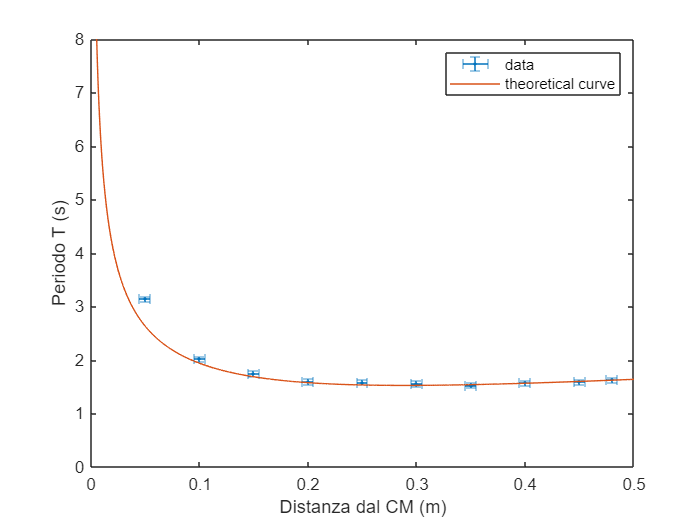


% plotting
plt=figure;
errorbar(d,tm,dtm,dtm,dd,dd,'.')
xlabel('Distanza dal CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
hold on
plot(r,tt)
hold off
ylim([0,8])
legend('data','theoretical curve')




% df2(df2.distance=="d1","time") % sostituire "d1" con gli elementi degli array
% mean(table2array(df2(df2.distance=="d1","time")))

% exporting csv
% writetable(array2table(namearray,'VariableNames',{'acceleration','uncertainty','uom','relative_error'}),'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
saveas(plt,'..\img\plot.png');

% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);